# **Controllo di un veicolo differential-drive**

Si consideri un veicolo a trazione differenziale, cioè un veicolo costituito da un sistema di trazione differenziale che permette alle ruote di muoversi (e quindi ruotare) a velocità differenti, l'una indipendentemente dall'altra.

## Descrizione del sistema

La dinamica di un veicolo a trazione differenziale può essere schematizzata come segue:

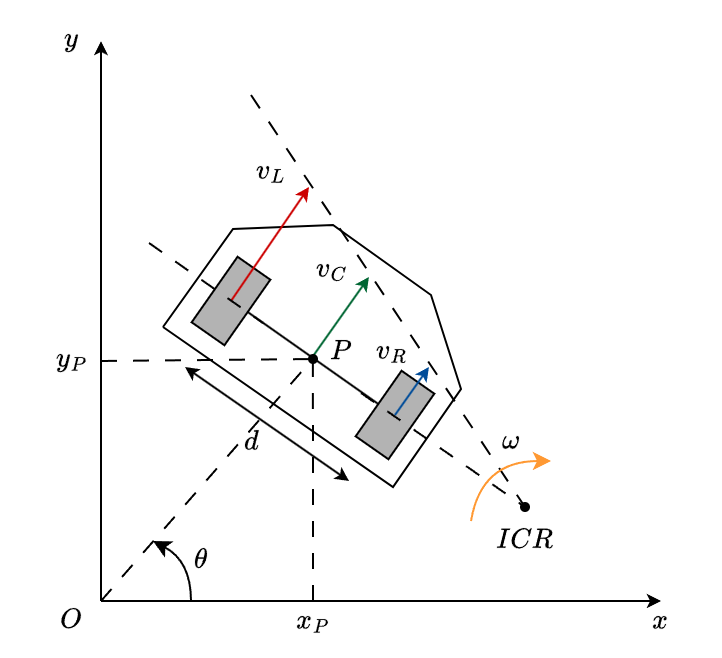

### Velocità lineare

Definite $v_L$ la velocità lineare assunta dalla ruota sinistra e $v_R$ la velocità lineare assunta dalla ruota destra, la velocità lineare assunta dal veicolo a guida differenziale $v_C$ è espressa come la media aritmetica tra le velocità lineari assunte dalle due ruote del veicolo:


$$v_C =\frac{v_L +v_R }{2}$$


Da un punto di vista vettoriale, la velocità lineare del veicolo rappresenta quel vettore, perpendicolare all'asse delle ruote, che interseca nel suo punto medio l'asse congiungente le punte dei due vettori associati alle velocità lineari delle ruote del veicolo.

### Centro di rotazione

Si definisce inoltre Istantaneous Center of Rotation (ICR) il punto di intersezione tra l'asse delle ruote e l'asse delle velocità delle ruote. L'ICR rappresenta il punto in corrispondenza del quale il veicolo a trazione differenziale esegue la sua rotazione.

### Velocità angolare

È interessante notare come, se le ruote si muovono in senso opposto, la velocità lineare assunta dal veicolo è nulla.

Basi pensare che l'asse congiungente i vettori delle velocità lineari assunte dalle due ruote intersecherebbe l'asse delle ruote, dunque alla velocità lineare del veicolo sarà associato un vettore nullo (cioè degenerato nel punto di intersezione tra i due assi). 

Nonostante la velocità lineare risultante sia nulla, il veicolo esegue una rotazione attorno al suo stesso asse, in quanto l'ICR corrisponde con il centro dell'asse delle ruote, con una velocità angolare $\omega$ che può essere ricavata come segue:


$$\omega =\frac{v_R -v_L }{d}$$


essendo $d$ la lunghezza dell'asse che congiunge il centro delle due ruote del veicolo a trazione differenziale.

### Relazione tra velocità

Con riferimento ad una ruota, la velocità angolare indica la velocità con la quale si muove la ruota mentre la velocità lineare indica la velocità sviluppata a contatto con l'asfalto. Tali velocità sono proporzionali secondo un fattore rappresentato dal raggio $R$ della ruota.


$$v=R\cdot \omega \;$$


## Modellazione del sistema

Per pianificare la traiettoria di un veicolo a trazione differenziale, è necessario conoscere come evolve la sua posizione nel tempo.

Se si astrae la struttura del veicolo ad un punto materiale, posizionato al centro dell'asse delle ruote, è possibile identificare la posizione del veicolo attraverso le coordinate $P\left(x_P ,y_P \right)$ e l'applicazione basilare della legge del moto rettilineo uniforme:


$$\begin{cases}
x_{P\text{ }}(k+1) =  x_{P\text{ }}(k)+v_{x\text{ }}(k)\cdot\Delta T \\
y_{P\text{ }}(k+1) =  y_{P\text{ }}(k)+v_{y\text{ }}(k)\cdot\Delta T
\end{cases}$$


dove $v_x$ e $v_y$ rappresentano le proiezioni della velocità lineare del veicolo rispetto ai corrispettivi assi del sistema di riferimento considerato, mentre $\Delta T$ rappresenta la differenza tra due istanti di tempo consecutivi, cioè il passo di campionamento.

Poiché l'angolazione del veicolo rispetto al sistema di riferimento non è nota, dunque non è possibile calcolare il valore che assumono le componenti di velocità in ogni istante, occorre considerare un'ulteriore equazione data dalla legge del moto rettilineo circolare:


$$\theta \left(k+1\right)=\theta \left(k\right)+\omega \cdot \Delta T$$


In questo modo è possibile ricavare le componenti sull'asse x e sull'asse y della velocità lineare assunta dal veicolo:


$$\begin{cases}
v_{x\text{ }}(k) =  v(k)\cos\left(\theta(k)\right) \\
v_{y\text{ }}(k) =  v(k)\sin\left(\theta(k)\right)
\end{cases}$$


### Equazioni di stato

Considerate come variabili di stato:

- $x_{1\;} \left(k\right)$ la coordinata sull'asse x del punto rappresentante il veicolo

- $x_{2\;} \left(k\right)$ la coordinata sull'asse y del punto rappresentante il veicolo

- $x_{3\;} \left(k\right)$ l'orientamento del punto rappresentante il veicolo rispetto al sistema di riferimento

e come ingressi:

- $u_{1\;} \left(k\right)$ la velocità lineare assunta dal veicolo

- $u_{2\;} \left(k\right)$ la velocità angolare assunta dal veicolo

le equazioni di stato del sistema sono:


$$\begin{cases}
x_{1\text{ }}(k+1) =  x_{1}(k)+u_{1}(k)\cos\left(x_3(k)\right)\cdot\Delta T \\
x_{2\text{ }}(k+1) =  x_{2}(k)+u_{1}(k)\sin\left(x_3(k)\right)\cdot\Delta T \\
x_{3\text{ }}(k+1) = x_{3}(k) + u_{2\text{ }}(k)\cdot\Delta T \ \ \ \ \ \ \ \ 
\end{cases}$$


## Implementazione del sistema

% Operazioni preliminari
close all;
clear all; 
clc;

### Funzione di stato

Poiché il sistema descritto è non lineare, occorre dichiarare separatamente la funzione di stato ([`ddStateFunction.m`](matlab:open('./ddStateFunction.m'))`).`

### Funzione di uscita

Poiché il sistema descritto è non lineare, occorre dichiarare separatamente la funzione di uscita ([`ddOutputFunction.m`](matlab:open('./ddOutputFunction.m'))`).`

## Controllo del sistema

Una volta implementato il sistema non lineare attraverso le sue funzioni di stato e di uscita, è necessario definire il controllore MPC.

% Numero di stati
nx = 3;

% Numero di uscite
ny = 3;

% Numero di ingressi
nu = 2;

### Definizione del controllore

% Controllore MPC
mpcobj = nlmpc(nx,ny,nu);

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.


Poiché il numero di uscite è maggiore del numero di ingressi, di default MATLAB assegna un peso nullo sulle uscite eccedenti il numero di ingressi. In questo caso, poiché gli ingressi sono 2 e le uscite sono 3, alla terza uscita viene assegnato peso nullo.

### Funzioni del sistema

Occorre specificare la funzione di stato e la funzione di uscita del sistema non lineare.

% Funzione di stato
mpcobj.Model.StateFcn = 'ddStateFunction';

% Funzione di uscita
mpcobj.Model.OutputFcn = 'ddOutputFunction';

Inoltre, va specificato che il sistema non lineare è tempo discreto.

% Sistema tempo discreto
mpcobj.Model.IsContinuousTime = false;

### Parametri del controllore

Si definiscono i parametri del controllore, che in questo specifico caso corrispondono a quelli di default di MATLAB:

% Periodo di campionamento
Ts = 0.1;

% Orizzonte di predizione
Hp = 10;

% Orizzonte di controllo
Hc = 2;

e li si assegnano al controllore accedendo alle rispettive proprietà:

% Periodo di campionamento
mpcobj.Ts = Ts;

% Orizzonte di predizione
mpcobj.PredictionHorizon = Hp;

% Orizzonte di controllo
mpcobj.ControlHorizon = Hc;

### Simulazione del controllo

Si supponga di voler controllare il veicolo in modo che si porti dalla posizione iniziale (0,0) a quella finale (1,1) con angolazione nulla.

% Riferimento
ref = [1, 1, 0];

Per verificare il corretto funzionamento del controllo, si esegue una simulazione di 5 secondi:

% Durata della simulazione
Tf = 5;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(1,3);
mv = zeros(1,2);

% Inizializzazione delle uscite
y_history = zeros(N,3);

% Inizializzazione degli ingressi
u_history = zeros(N,2);

% Ciclo di simulazione
for i=1:N

    [mv,~,info] = nlmpcmove(mpcobj,xk,mv,ref);

    % Aggiornamento
    xk = info.Xopt(2,:);
    y_history(i,:) = info.Yopt(1,:);
    u_history(i,:) = mv;
end

dove il campo `mv` contiene i valori ottimali degli ingressi di controllo ed il campo `info` contiene l'intera evoluzione del sistema.

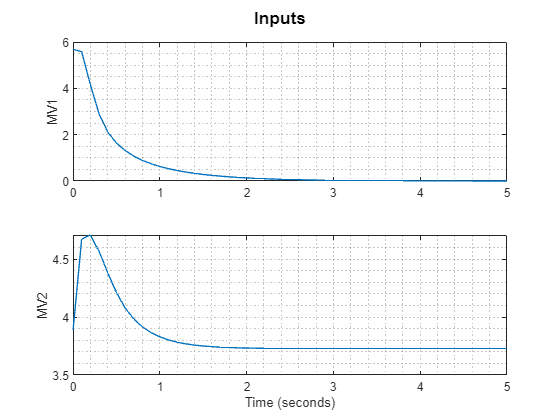

% Evoluzione degli ingressi
figure

subplot(2,1,1);
plot(t,u_history(:,1)),
grid minor,
ylabel('MV1');

subplot(2,1,2);
plot(t,u_history(:,2)),
grid minor,
xlabel('Time (seconds)'), ylabel('MV2');

sgtitle('Inputs', 'FontWeight', 'bold');

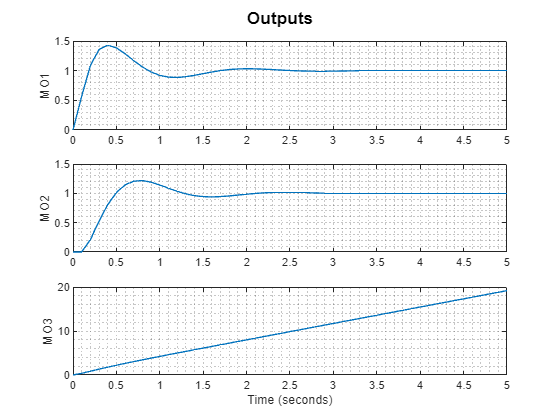



% Evoluzione delle uscite
figure

subplot(3,1,1);
plot(t,y_history(:,1)),
grid minor,
ylabel('MO1');

subplot(3,1,2);
plot(t,y_history(:,2)),
grid minor,
ylabel('MO2');

subplot(3,1,3);
plot(t,y_history(:,3)),
grid minor,
xlabel('Time (seconds)'), ylabel('MO3');

sgtitle('Outputs', 'FontWeight', 'bold');

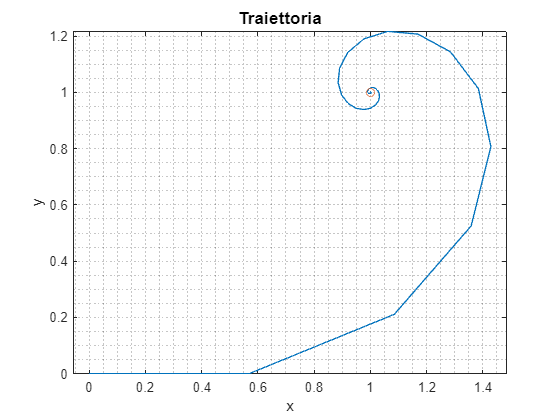



% Evoluzione della traiettoria
figure

plot(y_history(:,1),y_history(:,2)),
hold on, scatter(1,1),
grid minor, axis equal,
xlabel('x'), ylabel('y');

sgtitle('Traiettoria', 'FontWeight', 'bold');

### Analisi dei risultati

I risultati forniti dalla simulazione del controllo evidenziano la buona riuscita della pianificazione della traiettoria. Tuttavia si osserva come, per pervenire alla posizione desiderata, il controllore abbia fatto seguire un percorso inusuale e molto più complesso del dovuto.

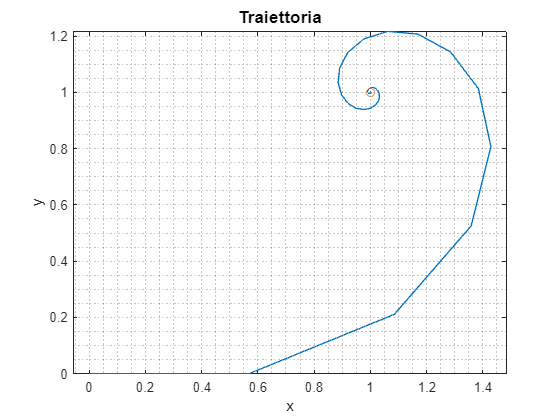

## Vincoli del sistema

Un rapido sguardo agli ingressi di controllo suggerisce la necessità di limitarli in fase di partenza del veicolo.

### Vincolo sul primo ingresso

Si può pensare di limitare il primo ingresso di controllo, cioè la velocità lineare del veicolo, in un intervallo unitario: $-1<u_{1\;} \left(k\right)<1$.

% Vincolo sul valore minimo del primo ingresso
mpcobj.ManipulatedVariables(1).Min = -1;

% Vincolo sul valore massimo del primo ingresso
mpcobj.ManipulatedVariables(1).Max = 1;

Si esegue nuovamente la simulazione per verificare se il vincolo sugli ingressi abbia effetto sulla traiettoria seguita.

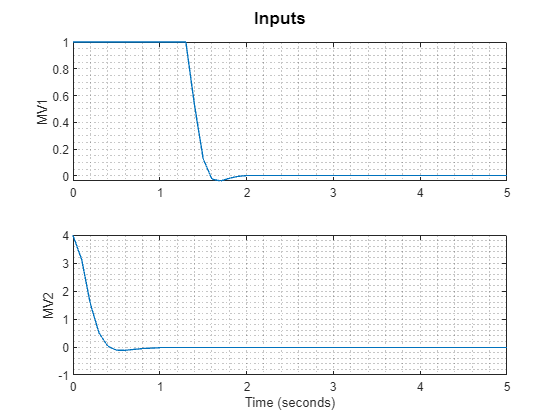

% Durata della simulazione
Tf = 5;

% Vettore dei tempi
t = 0:Ts:Tf;

% Numero di istanti di tempo
N = length(t);

% Inizializzazione
xk = zeros(1,3);
mv = zeros(1,2);

% Inizializzazione delle uscite
y_history = zeros(N,3);

% Inizializzazione degli ingressi
u_history = zeros(N,2);

% Riferimento
ref = [1, 1, 0];

% Ciclo di controllo
for i=1:N
    
    [mv,~,info] = nlmpcmove(mpcobj,xk,mv,ref);

    % Aggiornamento
    xk = info.Xopt(2,:);
    y_history(i,:) = info.Yopt(1,:);
    u_history(i,:) = mv;
end

% Evoluzione degli ingressi
figure

subplot(2,1,1);
plot(t,u_history(:,1)),
grid minor,
ylabel('MV1');

subplot(2,1,2);
plot(t,u_history(:,2)),
grid minor,
xlabel('Time (seconds)'), ylabel('MV2');

sgtitle('Inputs', 'FontWeight', 'bold');

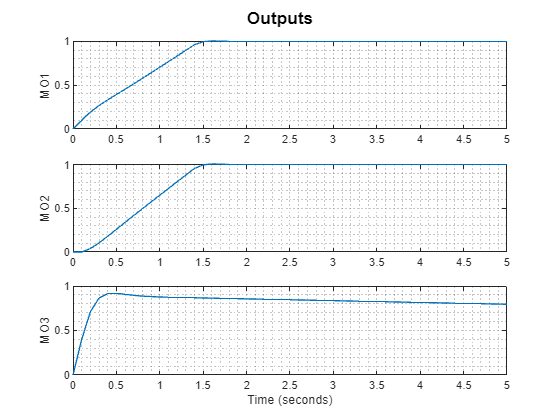


% Evoluzione delle uscite
figure

subplot(3,1,1);
plot(t,y_history(:,1)),
grid minor,
ylabel('MO1');

subplot(3,1,2);
plot(t,y_history(:,2)),
grid minor,
ylabel('MO2');

subplot(3,1,3);
plot(t,y_history(:,3)),
grid minor,
xlabel('Time (seconds)'), ylabel('MO3');

sgtitle('Outputs', 'FontWeight', 'bold');

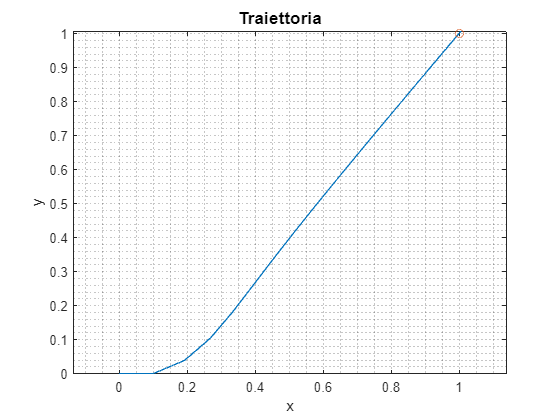


% Evoluzione della traiettoria
figure

plot(y_history(:,1),y_history(:,2)),
hold on, scatter(1,1),
grid minor, axis equal,
xlabel('x'), ylabel('y');

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati forniti dalla simulazione evidenziano in primo luogo come il vincolo sul primo ingresso sia ora soddisfatto.

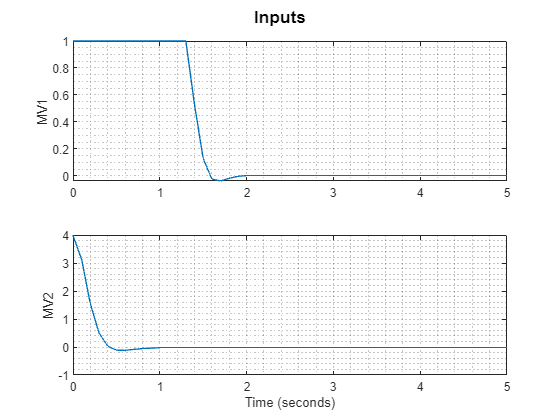

Il controllore è in grado di imporre traiettoria lineare, meno caotica rispetto al caso senza vincolo, con un angolo di arrivo di circa 45 gradi.

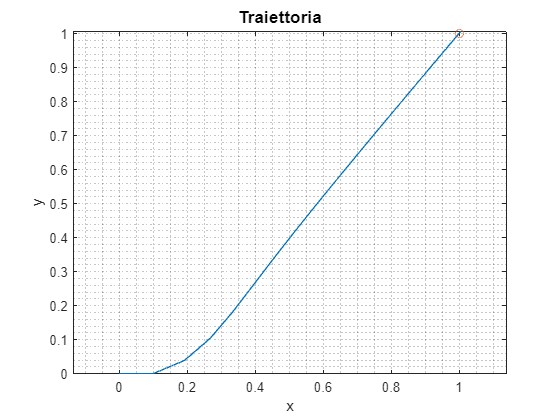

Poiché la posizione angolare e la velocità angolare sono espresse in termini di radianti, conviene convertire usando la funzione `rad2deg()`.

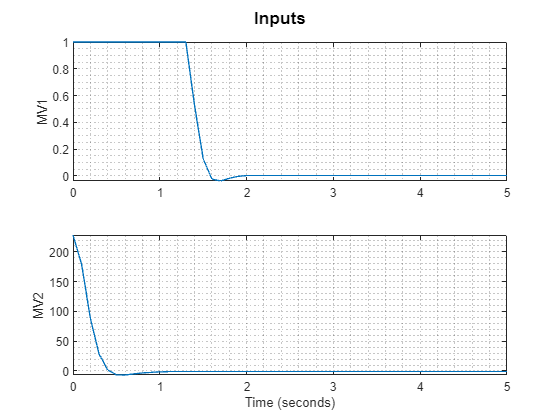

% Evoluzione degli ingressi
figure

subplot(2,1,1);
plot(t,u_history(:,1)),
grid minor,
ylabel('MV1');

subplot(2,1,2);
plot(t,rad2deg(u_history(:,2))),
grid minor,
xlabel('Time (seconds)'), ylabel('MV2');

sgtitle('Inputs', 'FontWeight', 'bold');

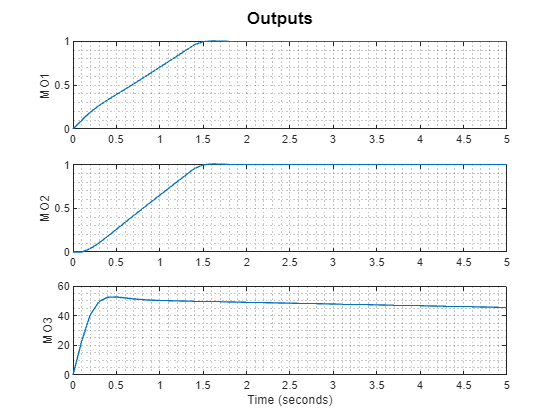


% Evoluzione delle uscite
figure

subplot(3,1,1);
plot(t,y_history(:,1)),
grid minor,
ylabel('MO1');

subplot(3,1,2);
plot(t,y_history(:,2)),
grid minor,
ylabel('MO2');

subplot(3,1,3);
plot(t,rad2deg(y_history(:,3))),
grid minor,
xlabel('Time (seconds)'), ylabel('MO3');

sgtitle('Outputs', 'FontWeight', 'bold');


% Evoluzione della traiettoria
figure

plot(y_history(:,1),y_history(:,2)),
hold on, scatter(1,1),
grid minor, axis equal,
xlabel('x'), ylabel('y');

sgtitle('Traiettoria', 'FontWeight', 'bold');

Come predetto, l'orientamento del veicolo espresso dalla terza uscita si assesta su un valore di circa 45 gradi.

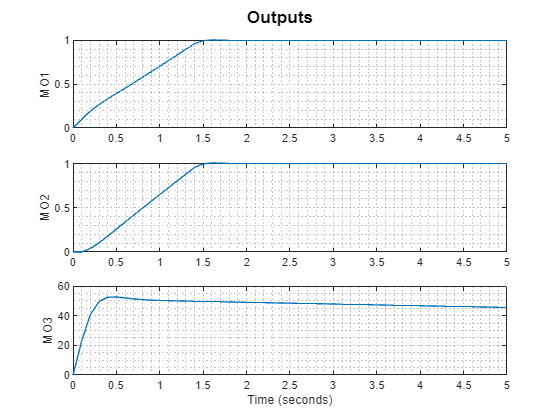

### Vincolo sul secondo ingresso

La conversione in gradi suggerisce di limitare anche il secondo ingresso di controllo, cioè la velocità angolare del veicolo.

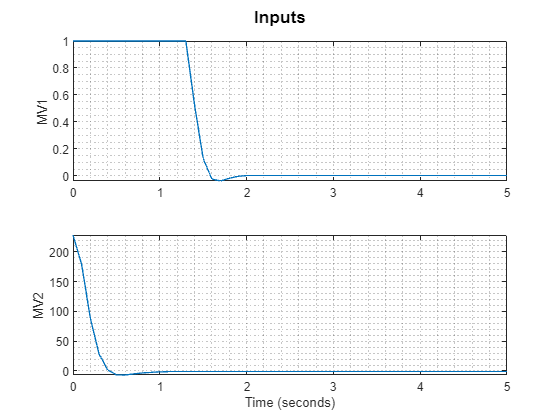

Un intervallo più consono potrebbe essere $-90\;\frac{\deg }{\mathrm{s}}\le u_{2\;} \left(k\right)\le 90\;\frac{\deg }{\mathrm{s}}$. In tal caso conviene specificare i limiti usando la funzione `deg2rad()`.

% Vincolo sul valore minimo del secondo ingresso
mpcobj.ManipulatedVariables(2).Min = -deg2rad(90);

% Vincolo sul valore massimo del secondo ingresso
mpcobj.ManipulatedVariables(2).Max = deg2rad(90);

Si esegue nuovamente la simulazione per verificare se il vincolo sugli ingressi abbia effetto sulla traiettoria seguita.

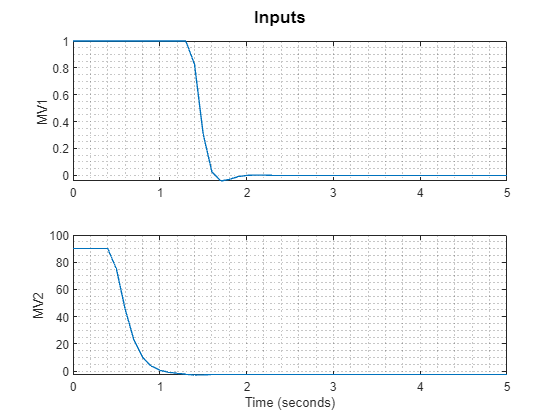

% Durata della simulazione
Tf = 5;

% Vettore dei tempi
t = 0:Ts:Tf;

% Numero di istanti di tempo
N = length(t);

% Inizializzazione
xk = zeros(1,3);
mv = zeros(1,2);

% Inizializzazione delle uscite
y_history = zeros(N,3);

% Inizializzazione degli ingressi
u_history = zeros(N,2);

% Riferimento
ref = [1, 1, 0];

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(mpcobj,xk,mv,ref);

    % Aggiornamento
    xk = info.Xopt(2,:);
    y_history(i,:) = info.Yopt(1,:);
    u_history(i,:) = mv;
end

% Evoluzione degli ingressi
figure

subplot(2,1,1);
plot(t,u_history(:,1)),
grid minor,
ylabel('MV1');

subplot(2,1,2);
plot(t,rad2deg(u_history(:,2))),
grid minor,
xlabel('Time (seconds)'), ylabel('MV2');

sgtitle('Inputs', 'FontWeight', 'bold');

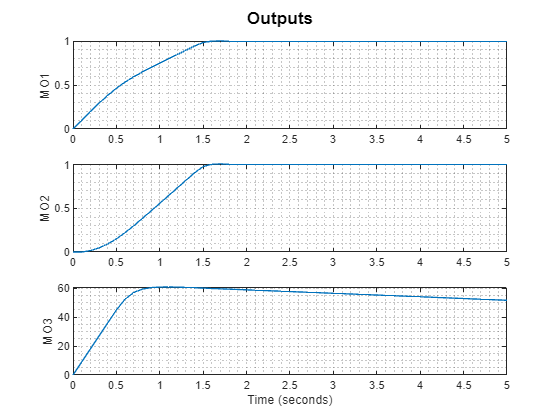


% Evoluzione delle uscite
figure

subplot(3,1,1);
plot(t,y_history(:,1)),
grid minor,
ylabel('MO1');

subplot(3,1,2);
plot(t,y_history(:,2)),
grid minor,
ylabel('MO2');

subplot(3,1,3);
plot(t,rad2deg(y_history(:,3))),
grid minor,
xlabel('Time (seconds)'), ylabel('MO3');

sgtitle('Outputs', 'FontWeight', 'bold');

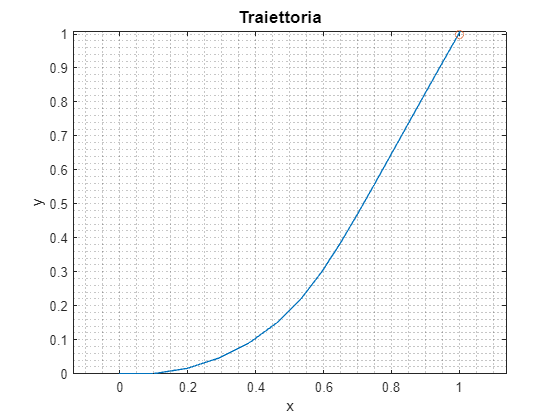


% Evoluzione della traiettoria
figure

plot(y_history(:,1),y_history(:,2)),
hold on, scatter(1,1),
grid minor, axis equal,
xlabel('x'), ylabel('y');

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati forniti dalla simulazione evidenziano in primo luogo come il vincolo sul secondo ingresso sia ora soddisfatto.

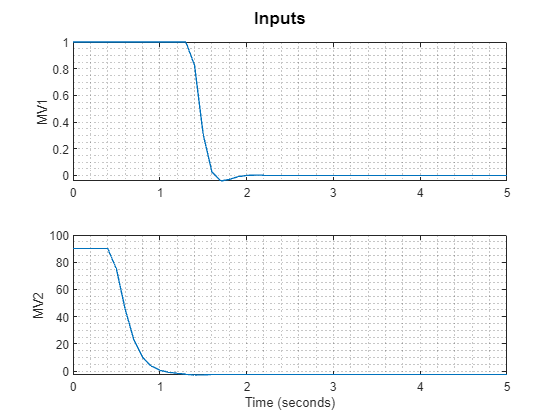

Si osserva inoltre una curvatura maggiore nella traiettoria pianificata dal controllore, indice delle limitazioni imposte sulla velocità angolare.

### Confronto con il riferimento

Può essere interessante osservare come cambia a runtime il riferimento elaborato dal controllore per raggiungere la posizione desiderata.

% Durata della simulazione
Tf = 5;

% Vettore dei tempi
t = 0:Ts:Tf;

% Numero di istanti di tempo
N = length(t);

% Inizializzazione
xk = zeros(1,3);
mv = zeros(1,2);

% Inizializzazione delle uscite
y_history = zeros(N,3);

% Inizializzazione degli ingressi
u_history = zeros(N,2);

% Inizializzazione dei riferimenti
r_history = zeros(N,3);

% Riferimento
ref = [1, 1, 0];

% Ciclo di controllo
for i=1:N
    [mv,~,info] = nlmpcmove(mpcobj,xk,mv,ref);

    % Aggiornamento
    xk = info.Xopt(2,:);
    y_history(i,:) = info.Yopt(1,:);
    u_history(i,:) = mv;
    r_history(i,:) = ref;
end

% Evoluzione degli ingressi
figure

subplot(2,1,1);
plot(t,u_history(:,1)),
grid minor,
ylabel('MV1');

subplot(2,1,2);
plot(t,rad2deg(u_history(:,2))),
grid minor,
xlabel('Time (seconds)'), ylabel('MV2');

sgtitle('Inputs', 'FontWeight', 'bold');

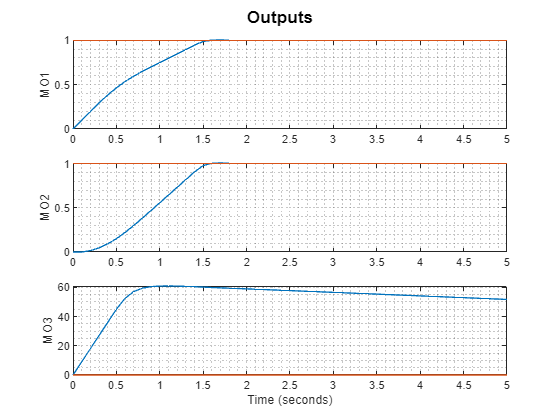


% Evoluzione delle uscite
figure

subplot(3,1,1);
plot(t,y_history(:,1)),
grid minor, hold on,
plot(t,r_history(:,1)),
ylabel('MO1');

subplot(3,1,2);
plot(t,y_history(:,2)),
grid minor, hold on,
plot(t,r_history(:,2)),
ylabel('MO2');

subplot(3,1,3);
plot(t,rad2deg(y_history(:,3))),
grid minor, hold on,
plot(t,r_history(:,3)),
xlabel('Time (seconds)'), ylabel('MO3');

sgtitle('Outputs', 'FontWeight', 'bold');

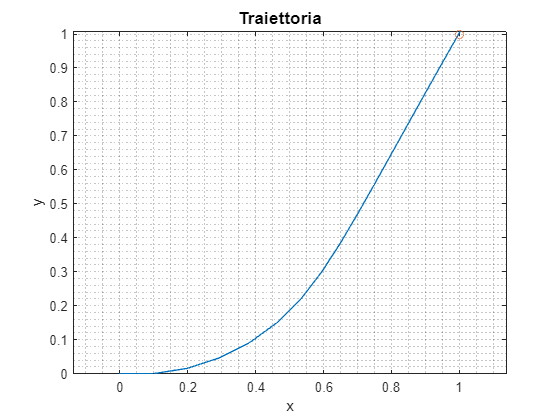


% Evoluzione della traiettoria
figure

plot(y_history(:,1),y_history(:,2)),
hold on, grid minor, axis equal,
scatter(r_history(:,1),r_history(:,2)),
xlabel('x'), ylabel('y');

sgtitle('Traiettoria', 'FontWeight', 'bold');

## Controllo avanzato del sistema

Si supponga infine di voler pianificare una traiettoria più complessa, ad esempio un quadrato, imponendo il passaggio per i seguenti punti:


$$\left(0,0\right)\to \left(1,0\right)\to \left(1,1\right)\to \left(0,1\right)$$


È necessario implementare un riferimento dinamico nel ciclo di simulazione che cambia al valore successivo del riferimento desiderato ogni volta che il veicolo si avvicina al valore corrente del riferimento desiderato. Una logica di questo tipo può essere implementata andando a commutare il riferimento al suo valore successivo nel momento in cui la funzione costo nel campo `info` scende al di sotto di una certa soglia.

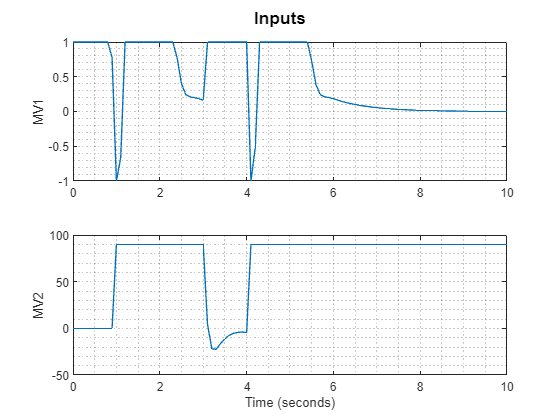

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Numero di istanti di tempo
N = length(t);

% Inizializzazione
xk = zeros(1,3);
mv = zeros(1,2);

% Inizializzazione delle uscite
y_history = zeros(N,3);

% Inizializzazione degli ingressi
u_history = zeros(N,2);

% Inizializzazione dei riferimenti
r_history = zeros(N,3);

% Riferimento 
ref = [1, 0, 0;
       1, 1, 0;
       0, 1, 0;
       0, 0, 0];
refIndex = 1;

% Ciclo di controllo
for i=1:N
    [mv,~,info] = nlmpcmove(mpcobj,xk,mv,ref(refIndex,:));

    % Riferimento dinamico
    J = info.Cost;
    if(J <= 0.03)
        if (refIndex < 4)
            % Commutazione
            refIndex = refIndex + 1;
        end
    end

    % Aggiornamento
    xk = info.Xopt(2,:);
    y_history(i,:) = info.Yopt(1,:);
    u_history(i,:) = mv;
    r_history(i,:) = ref(refIndex,:);
end

% Evoluzione degli ingressi
figure

subplot(2,1,1);
plot(t,u_history(:,1)),
grid minor,
ylabel('MV1');

subplot(2,1,2);
plot(t,rad2deg(u_history(:,2))),
grid minor,
xlabel('Time (seconds)'), ylabel('MV2');

sgtitle('Inputs', 'FontWeight', 'bold');

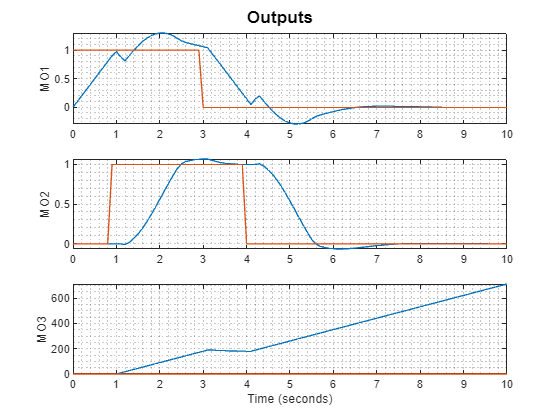


% Evoluzione delle uscite
figure

subplot(3,1,1);
plot(t,y_history(:,1)),
grid minor, hold on,
plot(t,r_history(:,1)),
ylabel('MO1');

subplot(3,1,2);
plot(t,y_history(:,2)),
grid minor, hold on,
plot(t,r_history(:,2)),
ylabel('MO2');

subplot(3,1,3);
plot(t,rad2deg(y_history(:,3))),
grid minor, hold on,
plot(t,r_history(:,3)),
xlabel('Time (seconds)'), ylabel('MO3');

sgtitle('Outputs', 'FontWeight', 'bold');

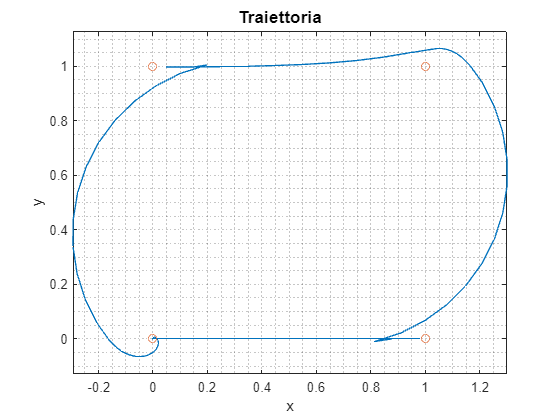


% Evoluzione della traiettoria
figure

plot(y_history(:,1),y_history(:,2)),
hold on, grid minor, axis equal,
scatter(r_history(:,1),r_history(:,2)),
xlabel('x'), ylabel('y');

sgtitle('Traiettoria', 'FontWeight', 'bold');

La simulazione evidenzia dei risultati soddisfacenti ma che lasciano spazio a evidenti miglioramenti nella strategia di controllo.